clear all; 

set(groot,'defaultAxesTickLabelInterpreter','latex');  
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');

Temporalv.v_X_CDS_32 =   csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\LineProbes\Mesh32\v_x_Re100_32_CDS.csv');
Temporalu.u_Y_CDS_32 =   csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\LineProbes\Mesh32\u_y_Re100_32_CDS.csv');
Temporalv.v_X_CDS_64 =   csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\LineProbes\Mesh64\v_x_Re100_64_CDS.csv');
Temporalu.u_Y_CDS_64 =   csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\LineProbes\Mesh64\u_y_Re100_64_CDS.csv');
Temporalv.v_X_CDS_128 =   csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\LineProbes\Mesh128\v_x_Re100_128_CDS.csv');
Temporalu.u_Y_CDS_128 =   csvread('C:\Users\IHarbi\Desktop\Master Thesis\NV REPO\NV_Stokes\NV_Stokes\LineProbes\Mesh128\u_y_Re100_128_CDS.csv');


x_over_L = [0, 0.0625, 0.0703, 0.0781, 0.0938, 0.1563, 0.2266, 0.2344, 0.5, 0.8047, 0.8594, 0.9063, 0.9453, 0.9531, 0.9609, 0.9688, 1];
v_Re100 = [0, 0.09233, 0.10091, 0.1089, 0.12317, 0.16077, 0.17507, 0.17527, 0.05454, -0.24533, -0.22445, -0.16914, -0.10313, -0.08864, -0.07391, -0.05906, 0];
v_Re1000 = [0.00000, 0.27485, 0.29012, 0.30353, 0.32627, 0.37095, 0.33075, 0.32235, 0.02526, -0.31966, -0.42665, -0.51550, -0.39188, -0.33714, -0.27669, -0.21388, 0.00000];
v_Re10000 = [0.00000, 0.43983, 0.43733, 0.43124, 0.41487, 0.35070, 0.28003, 0.27224, 0.00831, -0.30719, -0.36737, -0.41496, -0.45863, -0.49099, -0.52987, -0.54302, 0.00000];


y_over_L = [1, 0.9766, 0.9688, 0.9609, 0.9531, 0.8516, 0.7344, 0.6172, 0.5, 0.4531, 0.2813, 0.1719, 0.1016, 0.0703, 0.0625, 0.0547, 0];
u_Re100 = [1, 0.84123, 0.78871, 0.73722, 0.68717, 0.23151, 0.00332, -0.13641, -0.20581, -0.2109, -0.15662, -0.1015, -0.06434, -0.04775, -0.04192, -0.03717, 0];
u_Re1000 = [1.00000, 0.65928, 0.57492, 0.51117, 0.46604, 0.33304, 0.18719, 0.05702, -0.06080, -0.10648, -0.27805, -0.38289, -0.29730, -0.22220, -0.20196, -0.18109, 0.00000];
u_Re10000 = [1.00000, 0.47221, 0.47783, 0.48070, 0.47804, 0.34635, 0.20673, 0.08344, 0.03111, -0.07540, -0.23186, -0.32709, -0.38000, -0.41657, -0.42537, -0.42735, 0.00000];

% Sampling Size 
xq = 1000;
v_Re100_interp = interp1(x_over_L, v_Re100 , linspace(0, 1, xq), 'spline');
u_Re100_interp  =interp1(y_over_L, u_Re100, linspace(1, 0, xq), 'linear');

v_Re100_Ghia = [v_Re100_interp(xq/4) v_Re100_interp(3*xq/4)];
u_Re100_Ghia = [u_Re100_interp(xq/4) u_Re100_interp(3*xq/4)];

% L/4, 3L/4, H/4, 3H/4 
[Original_Size_32,L32]  = size(Temporalv.v_X_CDS_32  );
[Original_Size_64,L64]  = size(Temporalv.v_X_CDS_64  );
[Intrp_Size,L128]  = size(Temporalv.v_X_CDS_128  );

Idx_L32 = [ceil(L32/4) ceil(3*L32/4)];
Idx_L64 = [ceil(L64/4) ceil(3*L64/4)];
Idx_L128 = [ceil(L128/4) ceil(3*L128/4)];

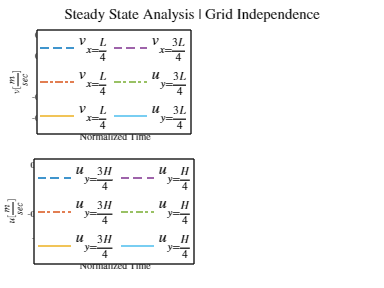


% Plotting Temporal Points Probes
% Choosing Points in the Domain: "L", "3L/4", "H/4", "3H/4".

v_X_CDS_32_L4 = interp1( linspace(0, 1, Original_Size_32), Temporalv.v_X_CDS_32 (:,Idx_L32(1) ), linspace(0, 1, Intrp_Size),  'spline');
v_X_CDS_32_3L4 = interp1( linspace(0, 1, Original_Size_32), Temporalv.v_X_CDS_32 (:,Idx_L32(2) ), linspace(0, 1, Intrp_Size),  'spline');
v_X_CDS_64_L4 = interp1( linspace(0, 1, Original_Size_64), Temporalv.v_X_CDS_64 (:,Idx_L64(1) ), linspace(0, 1, Intrp_Size),  'spline');
v_X_CDS_64_3L4 =interp1( linspace(0, 1, Original_Size_64), Temporalv.v_X_CDS_64 (:,Idx_L64(2) ), linspace(0, 1, Intrp_Size),  'spline');

subplot(2,2,1);
sgtitle('Steady State Analysis  | Grid Independence');
plot( Temporalv.v_X_CDS_128 (:,Idx_L128(1) ), 'LineStyle','--' ); hold on; 
plot( v_X_CDS_64_L4, 'LineStyle','-.');
plot( v_X_CDS_32_L4 );

plot( Temporalv.v_X_CDS_128 (:,Idx_L128(2) ) , 'LineStyle','--' );
plot( v_X_CDS_64_3L4, 'LineStyle','-.' );
plot( v_X_CDS_32_3L4 );

scatter(Intrp_Size + 1, v_Re100_Ghia(1), 'black', 'diamond', 'MarkerFaceColor','flat');
scatter(Intrp_Size + 1, v_Re100_Ghia(2), 'black', 'diamond', 'MarkerFaceColor','flat');
xlabel ('Normalized Time'); 
legend('$v_{x=\frac{L}{4}}$','$v_{x=\frac{L}{4}}$', '$v_{x=\frac{L}{4}}$','$v_{x=\frac{3L}{4}}$','$u_{y=\frac{3L}{4}}$','$u_{y=\frac{3L}{4}}$', 'Location','best' )
set(gca,'Xticklabel',[]);  ylabel('$v [\frac{m}{sec}]$');
legend(gca, 'NumColumns', 2, 'FontSize', 14);
grid minor; 




subplot(2,2,3);
u_Y_CDS_32_L4 = interp1( linspace(0, 1, Original_Size_32),  Temporalu.u_Y_CDS_32 (:,Idx_L32(1) ), linspace(0, 1, Intrp_Size));
u_Y_CDS_32_3L4 = interp1( linspace(0, 1, Original_Size_32), Temporalu.u_Y_CDS_32 (:,Idx_L32(2) ), linspace(0, 1, Intrp_Size));
u_Y_CDS_64_L4 = interp1( linspace(0, 1,  Original_Size_64), Temporalu.u_Y_CDS_64 (:,Idx_L64(1) ), linspace(0, 1, Intrp_Size));
u_Y_CDS_64_3L4 = interp1( linspace(0, 1, Original_Size_64), Temporalu.u_Y_CDS_64 (:,Idx_L64(2) ), linspace(0, 1, Intrp_Size));


plot( Temporalu.u_Y_CDS_128 (:,Idx_L128(2) ) , 'LineStyle','--' ); hold on; 
plot( u_Y_CDS_64_3L4, 'LineStyle','-.' );
plot( u_Y_CDS_32_3L4 );

plot( Temporalu.u_Y_CDS_128 (:,Idx_L128(1) ), 'LineStyle','--' ); 
plot( u_Y_CDS_64_L4, 'LineStyle','-.' );
plot( u_Y_CDS_32_L4 );

scatter(Intrp_Size + 1, u_Re100_Ghia(1), 'black', 'Marker','square', 'MarkerFaceColor','flat');
scatter(Intrp_Size + 1, u_Re100_Ghia(2), 'black','Marker','square', 'MarkerFaceColor','flat');
xlabel ('Normalized Time'); 
set(gca,'Xticklabel',[]) 
ylabel('$u [\frac{m}{sec}]$'); grid minor;
legend('$u_{y=\frac{3H}{4}}$','$u_{y=\frac{3H}{4}}$', '$u_{y=\frac{3H}{4}}$','$u_{y=\frac{H}{4}}$','$u_{y=\frac{H}{4}}$','$u_{y=\frac{H}{4}}$', 'Location','best')
legend(gca, 'NumColumns', 2, 'FontSize', 14); 

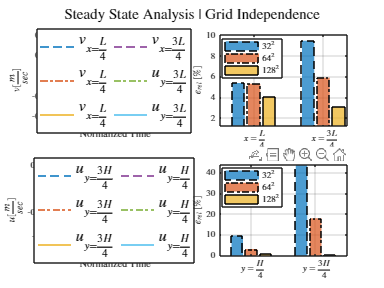

% Error Analysis | Bar Chart.
Err_v_X_P1  = [(v_Re100_Ghia(1) - Temporalv.v_X_CDS_128 (end,Idx_L128(1)))
    (v_Re100_Ghia(1) - Temporalv.v_X_CDS_64 (end,Idx_L64(1)))
    (v_Re100_Ghia(1) - Temporalv.v_X_CDS_32 (end,Idx_L32(1)))];
Err_v_X_P1_Percentage = abs(Err_v_X_P1./v_Re100_Ghia(1)).*100;

Err_v_X_P2  = [(v_Re100_Ghia(2) - Temporalv.v_X_CDS_128 (end,Idx_L128(2)))
    (v_Re100_Ghia(2) - Temporalv.v_X_CDS_64 (end,Idx_L64(2)))
    (v_Re100_Ghia(2) - Temporalv.v_X_CDS_32 (end,Idx_L32(2)))];
Err_v_X_P2_Percentage = abs(Err_v_X_P2./v_Re100_Ghia(2)).*100;



Err_u_Y_P1  = [(abs(u_Re100_Ghia(2)) - abs(Temporalu.u_Y_CDS_128 (end,Idx_L128(1))))
    (abs(u_Re100_Ghia(2)) - abs(Temporalu.u_Y_CDS_64 (end,Idx_L64(1))))
    (abs(u_Re100_Ghia(2)) - abs(Temporalu.u_Y_CDS_32 (end,Idx_L32(1))))];
Err_u_Y_P1_Percentage = abs(Err_u_Y_P1./abs(u_Re100_Ghia(2))).*100;

Err_u_Y_P2  = [(abs(u_Re100_Ghia(1)) - abs(Temporalu.u_Y_CDS_128 (end,Idx_L128(2))))
    (abs(u_Re100_Ghia(1)) - abs(Temporalu.u_Y_CDS_64 (end,Idx_L64(2))))
    (abs(u_Re100_Ghia(1)) - abs(Temporalu.u_Y_CDS_32 (end,Idx_L32(2))))];
Err_u_Y_P2_Percentage = abs(Err_u_Y_P2./abs(u_Re100_Ghia(1))).*100;
subplot(2,2,2);
Bar1 = bar([flipud(Err_v_X_P1_Percentage)'; flipud(Err_v_X_P2_Percentage)']); grid on;
set(Bar1(1),'LineStyle','--', 'FaceAlpha', 0.7);
set(Bar1(2),'LineStyle','-.', 'FaceAlpha', 0.7);
set(Bar1(3),'LineStyle','-' , 'FaceAlpha', 0.7);

ylabel('$\epsilon_{rel}$ [$\%$]');
xticklabels({'$x=\frac{L}{4}$', '$x=\frac{3L}{4}$'});
legend('$32^2$', '$64^2$', '$128^2$', 'Location', 'best');

subplot(2,2,4);
Bar2 = bar([flipud(Err_u_Y_P1_Percentage)'; flipud(Err_u_Y_P2_Percentage)']); grid on;
set(Bar2(1),'LineStyle','--', 'FaceAlpha', 0.7);
set(Bar2(2),'LineStyle','-.', 'FaceAlpha', 0.7);
set(Bar2(3),'LineStyle','-' , 'FaceAlpha', 0.7);
ylabel(' $\epsilon_{rel}$ [$\%$]');
xticklabels({'$y=\frac{H}{4}$', '$y=\frac{3H}{4}$'});
legend('$32^{2}$', '$64^{2}$', '$128^{2}$', 'Location', 'best');

# **Figure: Probes Locations.**